# **Quantization**

# *Sampling:*

## **1) Plot g(t)**

clear
t=linspace(0,2,20000);
gt=4+sin(2*pi*t)+cos(pi*t)+cos(pi*t/2)+tan(pi*t/6);
plot(t,gt);
xlabel("Time(s)","Interpreter","latex")
ylabel("g(t)","Interpreter","latex")
title("g(t)","Interpreter","latex")

## **2) Sampling with fs=300 Hz**

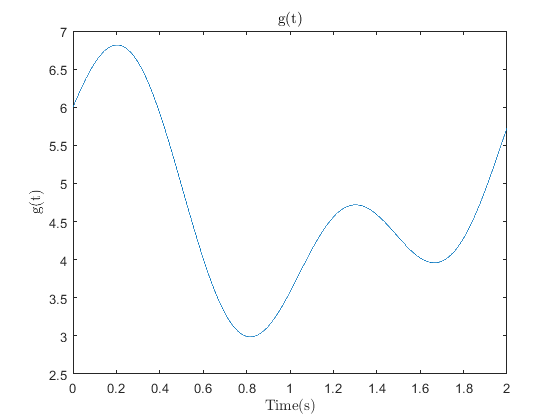

fs=300;
n=t(1:fs:length(t));
gn=gt(1:fs:length(gt));

plot(t,gt,"b");
hold on
stem(n,gn,"r");
hold off
xlabel("Time(s)","Interpreter","latex")
ylabel("g(t)","Interpreter","latex")
title("g(t) and g[n]","Interpreter","latex")
legend('g(t)','g[n]','Interpreter','latex')

# Quantization Levels:

## 3) Quantizing the Signal

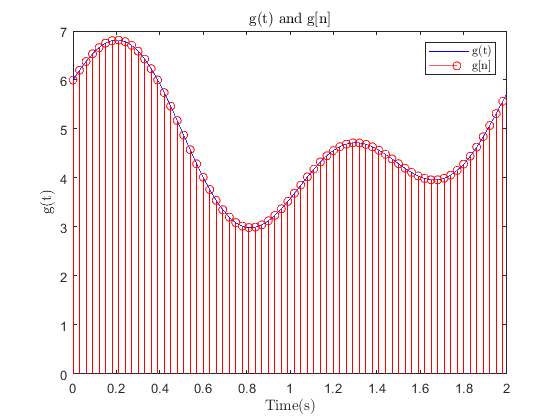

Levels=linspace(min(gn),max(gn),32);
delta=Levels(2)-Levels(1);
Quantized_gn=zeros(1,length(gn));
for i=1:length(gn)
    for k=1:1:length(Levels)-1

        if (((Levels(k))<=gn(i))&&(gn(i)<=(Levels(k+1))))
            if((gn(i)-Levels(k))<delta/2)
                 Quantized_gn(i)=Levels(k);
            else
                 Quantized_gn(i)=Levels(k+1);
            end
        end    
    end
end
plot(n,gn,"blue");
hold on
plot(n,Quantized_gn,"red")
hold off
xlabel("Time(s)","Interpreter","latex")
ylabel("Amplitude","Interpreter","latex")
title("Quantized g[n]","Interpreter","latex")
legend('g[n]',"$g_Q[n]$",'Interpreter','latex')

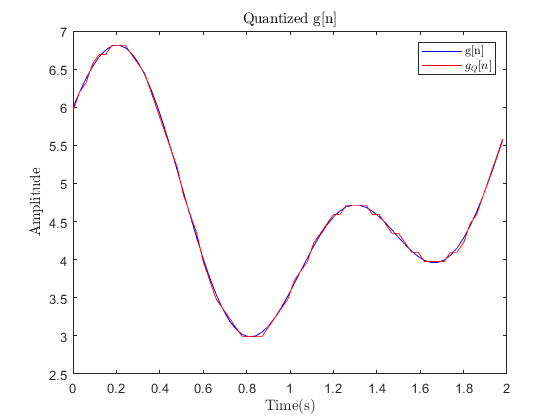

plot(n,gn,"bo");
hold on
plot(n,Quantized_gn,"m*")
Levels_plot=Levels.*ones(length(n),1);
plot(n,Levels_plot,"r")
hold off
xlabel("Time(s)","Interpreter","latex")
ylabel("Amplitude","Interpreter","latex")

title("Quantized g[n]","Interpreter","latex")
legend('g[n]',"$g_Q[n]$",'Interpreter','latex')

# Digitalizing the Quantized Signal

## 4) Rectangular Pulse Energy

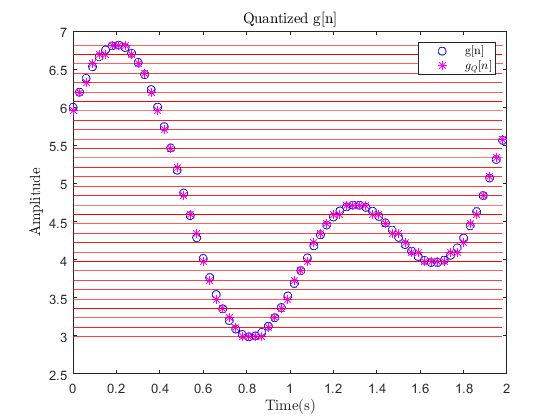

fs_con=20000;
t1=0:1/fs_con:1;
tri_pulse_t(1:0.5*fs_con)=2*t1(1:0.5*fs_con);
tri_pulse_t(0.5*fs_con+1:length(t1))=-2*t1(0.5*fs_con+1:length(t1))+2;
plot(t1,tri_pulse_t,"b")
fs_dis=1000;
n1=t1(1:fs_dis:length(t1));
tri_pulse_n=tri_pulse_t(1:fs_dis:length(tri_pulse_t));
hold on

stem(n1,tri_pulse_n,"r");
xlabel("Time(s)")
title("Pulse of Amplitude Modulation")
legend('Pulse(t)',"Pulse[n]",'Interpreter','latex')
hold off

## Pulse's Energy

Pulse=importdata("p.mat");
Energy=sum(Pulse.^2);
fprintf('The Energy of Discrete Pulse is %0.3f', Energy);

## 5) Gray Coding the Levels

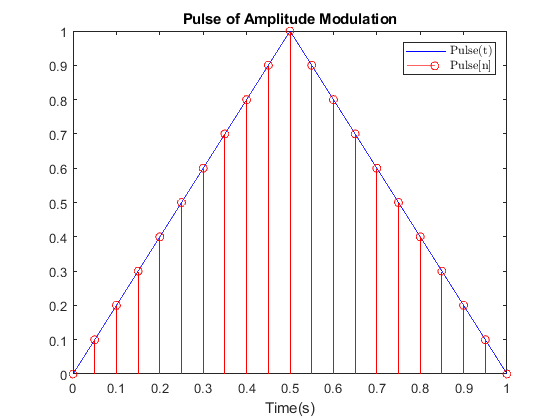

Decimal=-31:2:31;
gray_code=[00000 00001 00011 00010 00110 00111 00101 00100 01100 01101 01111 ...
           01110 01010 01011 01001 01000 11000 11001 11011 11010 11110 ...
           11111 11101 11100 10100 10101 10111 10110 10010 10011 10001 10000];
DGQ_Levels=zeros(length(Levels),3);
DGQ_Levels(:,1)=Decimal;
DGQ_Levels(:,2)=gray_code;
DGQ_Levels(:,3)=Levels;
coded_pulses=[]; %% for transfered pulses

for i=1:length(Quantized_gn)
    for j=1:length(Levels)
        if (Quantized_gn(i)==Levels(j))
            coded_pulses=[coded_pulses,Pulse.*DGQ_Levels(j,1)];
        end

The Energy of Discrete Pulse is 333.334

    end
end
t=0:1/fs_dis:length(Quantized_gn)-1/fs_dis;
fig15=figure(15);
plot(t,coded_pulses,"b")
xlabel("Time(s)")
ylabel("Amplitude")
title("Transfered Pulses")

# Recieving the Digital Signal in Reciever

## 6) Calculating Variance

bits=5;
q=2^bits;
SNR=10^2;
Sx=sum(coded_pulses.^2)/length(coded_pulses);
Var=Sx/SNR;
fprintf('The Variance of Gaussian Noise is %0.5f', Var);

## 7) Adding Gaussian Noise to the Signal

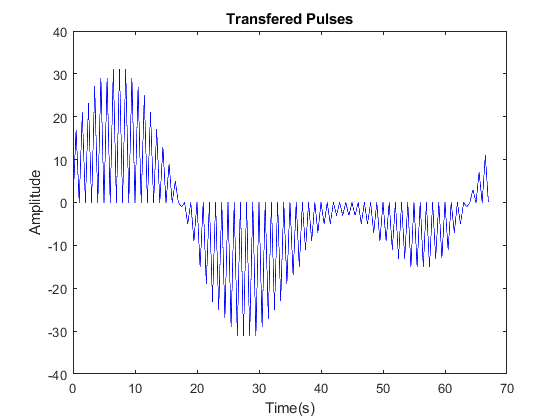

noise=normrnd(0,sqrt(Var),[1,length(coded_pulses)]);
noisy_coded_pulses=coded_pulses+noise;
plot(t,noisy_coded_pulses)
xlabel("Time(s)")
ylabel("Amplitude")
title("Recieved Signal in Reciever")

# Decoding the Digital Signal

## 8) Quantization Level Digit

mult_pulses=[];
for i=0:length(noisy_coded_pulses)/fs_dis-1
    mult_pulses=[mult_pulses,noisy_coded_pulses(i*fs_dis+1:(i+1)*fs_dis).*Pulse];
end
plot(mult_pulses)
xlabel("Time(s)")

The Variance of Gaussian Noise is 1.15836

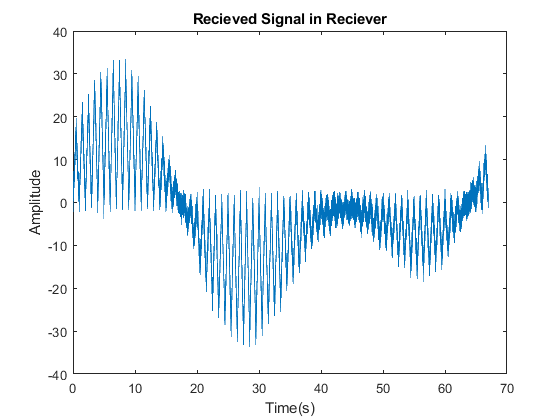

ylabel("Amplitude")
title("Multiplication of noisy signal and base pulse")
for k=1:length(mult_pulses)/fs_dis
    mult_pulses_Energy(k)=sum(mult_pulses((k-1)*fs_dis+1:k*fs_dis));
end
Amplitude=mult_pulses_Energy/Energy;
for i=1:length(Amplitude)
    for j=1:length(Levels)

        diff(j)=abs(Amplitude(i)-DGQ_Levels(j,1));
    end
    q_index=find(diff==min(diff));
    Level_Digits(i)=DGQ_Levels(q_index,1);
end
Level_Digits

## 9) Reconstruction of the Quantized Signal

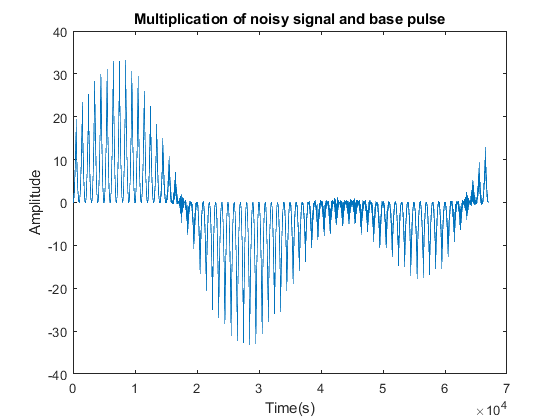

for m=1:length(Level_Digits)
    Indexes=find(DGQ_Levels(:,1)==Level_Digits(m));
    Reconstructed_Signal(m)=DGQ_Levels(Indexes,3);
end

plot(Quantized_gn,"c")
hold on
plot(Reconstructed_Signal,"r--");
xlabel("Time(s)")
ylabel("Amplitude")
title("Reconstruction of the Quantized Signal")
legend('Quantized g[n]',"Constructed g[n]",'Interpreter','latex')
hold off

## 10) Intersection Points

Quantized_gn_lower=ones(1,length(gn)).*max(Levels);

Level_Digits =     17    21    23    27    29    29    31    31    31    29    27    25    21    17    13     9     5    -1    -5    -9   -15   -19   -23   -25   -27   -29   -31   -31   -31   -31   -29   -27   -25   -23   -19   -17   -15   -11    -9    -7    -5    -5    -3    -3    -3    -3    -5    -5    -7    -9


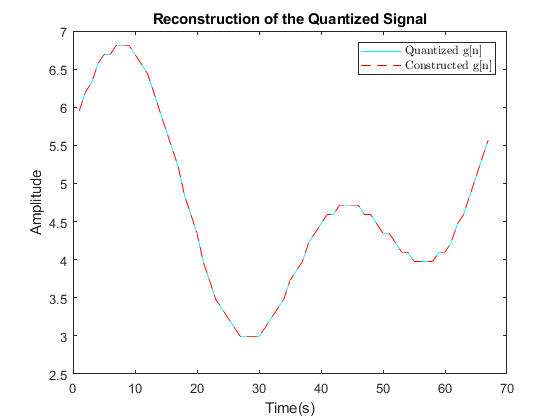

for i=1:length(gn)     %% Loop for locating the samples in lower level
    for k=1:1:length(Levels)-1
        if (((Levels(k))<=gn(i))&&(gn(i)<(Levels(k+1))))
             Quantized_gn_lower(i)=Levels(k);
        end
    end    
end
fig24=figure(24);
plot(gn,"bo");
hold on
plot(Quantized_gn_lower,"m*")
Levels_plot=Levels.*ones(length(n),1);
plot(Levels_plot,"r")
hold off

xlabel("Time(s)","Interpreter","latex")
ylabel("Amplitude","Interpreter","latex")
title("Quantized g[n]","Interpreter","latex")
legend('g[n]',"$g_Q[n]$",'Interpreter','latex')

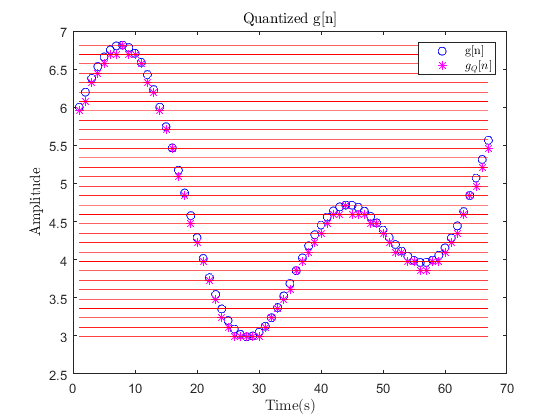

indx=0:length(Quantized_gn_lower)-1;
saved_points=[];  saved_index=[];
Q=Quantized_gn_lower;
saved_points=[saved_points,Q(1)];
saved_index=[saved_index,indx(1)];
for i=2:length(Q)-1
    for j = i+1:length(n)-1
        temp1 = Q(j);
        if(Q(i)~=Q(j))
            break
        end

    end
    for j = i-1:-1:1
        temp2 = Q(j);
        if(Q(i)~=Q(j))
            break
        end            
    end
    if((Q(i-1) < Q(i)) && (Q(i) <= Q(i+1))) %% Upward part of signal
        saved_points=[saved_points,Q(i)];
        saved_index=[saved_index,indx(i)];
    elseif((Q(i-1) >= Q(i)) && (Q(i) > Q(i+1))) %% Dawnward part of signal
        saved_points=[saved_points,Q(i)];
        saved_index=[saved_index,indx(i)];
    elseif(Q(i-1)<Q(i) && Q(i)>Q(i+1)) %% Maximum point  
        saved_points=[saved_points,Q(i)];
        saved_index=[saved_index,indx(i)];
    elseif(Q(i-1)>=Q(i) && Q(i)<=Q(i+1))  %% Minimum point 
        if(Q(i-1)>Q(i) && Q(i)<temp1 && Q(i)<temp2) %% Left side of minimum point 
            saved_points=[saved_points,Q(i)];
            saved_index=[saved_index,indx(i)];
        elseif(Q(i-1)==Q(i) && Q(i)<Q(i+1) && Q(i)<temp1 && Q(i)<temp2) %% Right side of minimum point 
            saved_points=[saved_points,Q(i)];
            saved_index=[saved_index,indx(i)];
        end
    end
end        
saved_points=[saved_points,Q(length(Q))];
saved_index=[saved_index,indx(end)];
plot(indx,Q,"bo");
hold on
plot(saved_index,saved_points,"m*")
Levels_plot=Levels.*ones(length(indx),1);
plot(indx,Levels_plot,"r")
hold off
xlabel("Time(s)","Interpreter","latex")
ylabel("Amplitude","Interpreter","latex")
title("Intersection points","Interpreter","latex")
legend('$g_Q[n]$',"Saved Point",'Interpreter','latex')

## 11) Interpolation

t=linspace(0,2,20000);
Interpolated=spline((saved_index)*fs/(length(t)/2),saved_points,t);
plot(gt,"b");
hold on
plot(Interpolated,"r")
hold off
xlabel("Time(s)","Interpreter","latex")
ylabel("Amplitude","Interpreter","latex")
title("Primary Analog Signal and Interpolated Signal","Interpreter","latex")
legend('$g(t)$',"Interpolated g(t)",'Interpreter','latex')

## 12) Error of Interpolated Signal and Primary Signal

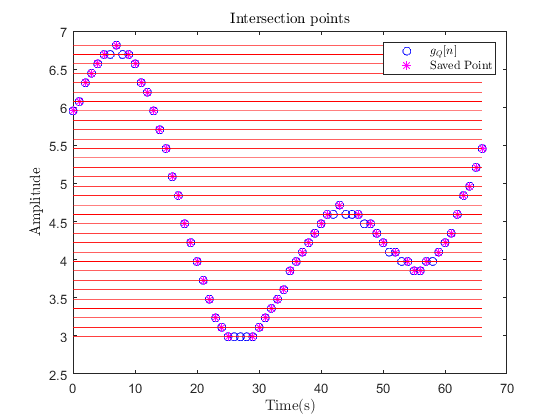

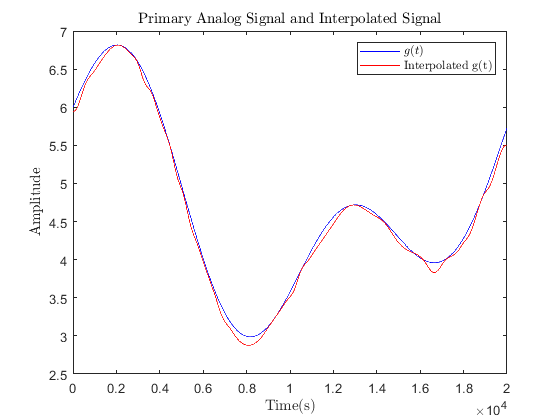

The Error of Interpolated and Primary Analog Signals is 0.00462

Error=immse(Interpolated,gt);
fprintf('The Error of Interpolated and Primary Analog Signals is %0.5f', Error);